%% EKF Localization - Single Trial Optimization
clear; clc;

% ========================
%% 1. Load and Prepare Data
% ========================
disp('Loading calibration data...');

Loading calibration data...


calib_rotate = load('calib1_rotate.mat');
calib_straight = load('calib2_straight.mat');

% Calibrate sensors (creates calib_params.mat)
disp('Calibrating sensors...');

Calibrating sensors...


calibrate_sensors(); 

IMU Calibration Error: The logical indices in position 1 contain a true value outside of the array bounds.
Available data: 72.9 seconds
Trying to use all available data...


Calibration successful!



% Load just ONE trial dataset
trial_num = 5; % Change this to select which trial to optimize
disp(['Loading task data for trial ', num2str(trial_num), '...']);

Loading task data for trial 5...


trial_data = load(sprintf('task2_%d.mat', trial_num));

% Prepare ground truth for this single trial
pos_data = trial_data.out.GT_position.signals.values(:,1:2);
rot_data = quat2eul(trial_data.out.GT_rotation.signals.values, 'ZYX');
GT_truth = [pos_data, rot_data(:,1)];

% ========================
%% 2. Single-Trial Parameter Optimization
% ========================
disp('Optimizing parameters for this trial...');

Optimizing parameters for this trial...


|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Q_pos |        Q_vel |        Q_yaw |        R_mag |   mag_thresh |   yaw_thresh |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |              |              |
|=================================================================================================================================================================|
|    1 | Best   |      278.61 |      0.1024 |      278.61 |      278.61 |    0.0035629 |     0.024195 |       0.0045 |     0.016661 |      0.54012 |       3.0164 |
|    2 | Accept |      331.44 |    0.087404 |      278.61 |      281.63 |     0.095598 |    0.0014485 |    2.255e-05 |     0.045153 |      0.27549 |       1.4618 |
|    3 | Best   

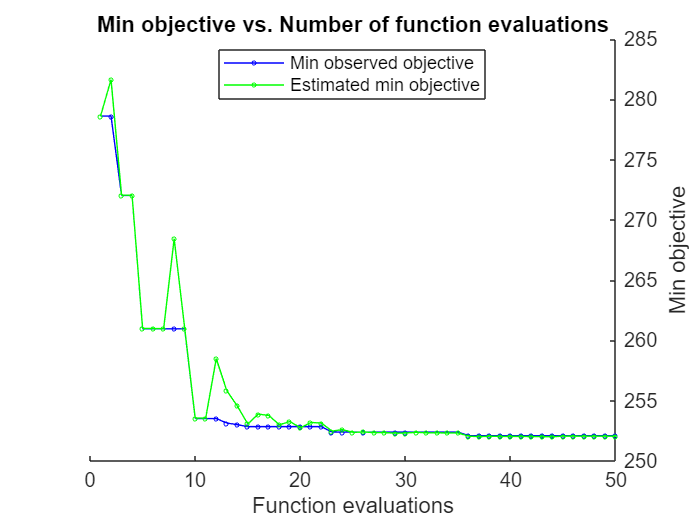


% Define optimization variables (same as before)
optVars = [
    optimizableVariable('Q_pos', [1e-4, 1e-1], 'Transform', 'log'),
    optimizableVariable('Q_vel', [1e-3, 1], 'Transform', 'log'),
    optimizableVariable('Q_yaw', [1e-5, 1e-2], 'Transform', 'log'),
    optimizableVariable('R_mag', [0.001, 0.1], 'Transform', 'log'),
    optimizableVariable('mag_thresh', [0.1, 1.5]),
    optimizableVariable('yaw_thresh', [pi/6, pi])
];

% Single-trial objective function
fun = @(params) computeRMSE(params, trial_data.out, GT_truth);

% Run optimization (serial mode)
results = bayesopt(fun, optVars, ...
    'MaxObjectiveEvaluations', 50, ... 
    'IsObjectiveDeterministic', false, ...
    'UseParallel', false);  % Disabled parallel mode


% Get best parameters
best_params = bestPoint(results);
disp('Best parameters for this trial:');

Best parameters for this trial:


disp(best_params);

      Q_pos        Q_vel        Q_yaw       R_mag      mag_thresh    yaw_thresh
    _________    _________    _________    ________    __________    __________

    0.0001005    0.0013729    0.0099928    0.016755     0.61762        1.4201  




% ========================
%% 3. Evaluate on This Trial
% ========================
disp('Evaluating on this trial with optimized parameters...');

Evaluating on this trial with optimized parameters...


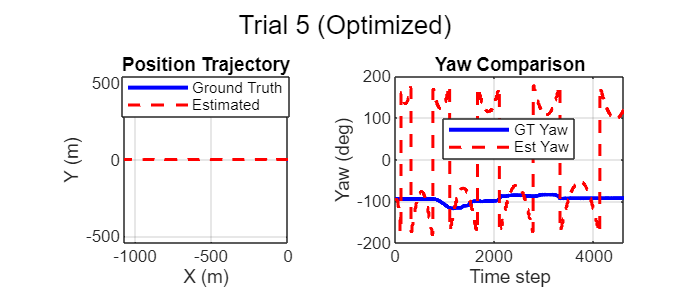


% Convert to struct format
ekf_params = struct();
ekf_params.Q = [best_params.Q_pos, best_params.Q_pos, best_params.Q_vel, ...
               best_params.Q_vel, best_params.Q_yaw, 0.001];
ekf_params.R_mag = best_params.R_mag;
ekf_params.mag_thresh = best_params.mag_thresh;
ekf_params.yaw_thresh = best_params.yaw_thresh;

% Run EKF with optimized parameters
[X_Est, ~, GT] = myEKF(trial_data.out, ekf_params);

% Compute RMSE
[pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT, ...
    trial_data.out.GT_rotation.signals.values);

% Visualize
visualizeTrajectory(X_Est, GT, sprintf('Trial %d (Optimized)', trial_num));


% ========================
%% 4. Display Results
% ========================
fprintf('\n=== Optimization Results ===\n');


=== Optimization Results ===


fprintf('Position RMSE: %.3f meters\n', pos_rmse);

Position RMSE: 508.313 meters


fprintf('Yaw RMSE: %.2f degrees\n\n', rad2deg(yaw_rmse));

Yaw RMSE: 93.72 degrees




% Save best parameters with trial number in filename
save(sprintf('optimized_ekf_params_trial%d.mat', trial_num), 'best_params');
disp(['Optimized parameters saved to optimized_ekf_params_trial', num2str(trial_num), '.mat']);

Optimized parameters saved to optimized_ekf_params_trial5.mat


function visualizeTrajectory(X_Est, GT, plotTitle)
    figure('Position', [100 100 1200 500]);
    
    % Position plot
    subplot(1,2,1);
    plot(GT(:,1), GT(:,2), 'b-', 'LineWidth', 2, 'DisplayName', 'Ground Truth');
    hold on;
    plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Estimated');
    axis equal;
    xlabel('X (m)'); ylabel('Y (m)');
    title('Position Trajectory');
    legend('Location', 'best');
    grid on;
    
    % Yaw plot
    subplot(1,2,2);
    t = 1:length(GT(:,3));
    plot(t, rad2deg(GT(:,3)), 'b-', 'LineWidth', 2, 'DisplayName', 'GT Yaw');
    hold on;
    plot(t, rad2deg(X_Est(:,5)), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Est Yaw');
    xlabel('Time step'); ylabel('Yaw (deg)');
    title('Yaw Comparison');
    legend('Location', 'best');
    grid on;
    
    sgtitle(plotTitle);
end

function [pos_rmse, yaw_rmse] = calculateRMSE(X_Est, GT_position, GT_rotation)
    pos_error = sqrt((X_Est(:,1) - GT_position(:,1)).^2 + ...
                    (X_Est(:,2) - GT_position(:,2)).^2);
    pos_rmse = sqrt(mean(pos_error.^2));
    
    gt_yaw = quat2eul(GT_rotation, 'ZYX');
    gt_yaw = gt_yaw(:,1);
    yaw_diff = wrapToPi(X_Est(:,5) - wrapToPi(gt_yaw));
    yaw_rmse = sqrt(mean(yaw_diff.^2));
end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end

function [X_Est, P_Est, GT] = myEKF(out, params)
    % Persistent calibration data
    persistent calib_params first_run;
    
    % Load calibration parameters on first run
    if isempty(first_run)
        load('calib_params.mat');
        calib_params = struct(...
            'accel_bias', accel_bias, ...
            'gyro_bias', gyro_bias, ...
            'A_mag', A_mag, ...
            'b_mag', b_mag, ...
            'tof_bias', tof_bias);
        first_run = false;
    end

    %% Parameter handling with defaults
    if nargin < 2
        params = struct();
    end
    
    % Process noise (optimizable)
    if isfield(params, 'Q')
        Q = diag(params.Q);
    else
        Q = diag([0.001, 0.001, 0.05, 0.05, 0.01, 0.01]); % Default values
    end
    
    % Measurement noise (optimizable)
    R_mag = getfield(params, 'R_mag', 0.01); % Magnetometer
    R_tof = getfield(params, 'R_tof', 0.1);  % ToF sensors
    
    % Magnetometer thresholds (optimizable)
    mag_thresh = getfield(params, 'mag_thresh', 0.5); % Field strength
    yaw_thresh = getfield(params, 'yaw_thresh', pi/2); % Update threshold
    
    %% Data extraction
    GT_time = double(out.GT_time.time);
    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;
    
    % Fix invalid quaternions
    zero_rows = all(GT_rotation==0,2);
    if any(zero_rows)
        GT_rotation(zero_rows,:) = repmat([1,0,0,0], sum(zero_rows), 1);
    end
    
    % Sensor data reshaping
    accel_data = reshapeSensorData(out.Sensor_ACCEL.signals.values);
    gyro_data = reshapeSensorData(out.Sensor_GYRO.signals.values);
    mag_data = squeeze(out.Sensor_MAG.signals.values)';
    tof1_data = out.Sensor_ToF1.signals.values;
    tof2_data = out.Sensor_ToF2.signals.values;
    tof3_data = out.Sensor_ToF3.signals.values;

    %% Initialization
    eul_angles = quat2eul(GT_rotation(1,:), 'ZYX');
    X = [GT_position(1,1); GT_position(1,2); 0; 0; eul_angles(1); 0];
    P = diag([0.1, 0.1, 0.5, 0.5, 0.1, 0.05]);
    
    %% Timing setup
    imu_dt = 1/104;  mag_dt = 1/50;  tof_dt = 1/10;
    imu_idx = 1; mag_idx = 1; tof_idx = 1;
    imu_time = 0; mag_time = 0; tof_time = 0;
    
    %% Main EKF loop
    n = length(GT_time);
    X_Est = zeros(n,6);
    P_Est = zeros(6,6,n);
    GT = zeros(n,3);
    
    for i = 1:n
        current_time = GT_time(i);
        
        %% IMU Prediction
        while (imu_idx <= size(accel_data,1)) && (imu_time <= current_time)
            % World-frame transformation
            R = [cos(X(5)) -sin(X(5)); sin(X(5)) cos(X(5))];
            a_body = accel_data(imu_idx,1:2)' - calib_params.accel_bias(1:2)';
            a_world = R * a_body;
            gyro_z = gyro_data(imu_idx,3) - calib_params.gyro_bias(3);
            
            % State prediction
            X = [X(1) + X(3)*imu_dt;
                 X(2) + X(4)*imu_dt;
                 X(3) + a_world(1)*imu_dt;
                 X(4) + a_world(2)*imu_dt;
                 X(5) + gyro_z*imu_dt;
                 gyro_z];
            
            % Covariance prediction
            F = [1 0 imu_dt 0      -X(4)*imu_dt            0;
                 0 1 0      imu_dt X(3)*imu_dt             0;
                 0 0 1      0      -a_world(2)*imu_dt      0;
                 0 0 0      0      a_world(1)*imu_dt       0;
                 0 0 0      0      1                  imu_dt;
                 0 0 0      0      0                      1];
            
            P = F * P * F' + Q;
            
            % Update IMU tracking
            imu_idx = imu_idx + 1;
            imu_time = imu_time + imu_dt;
        end
        
        %% Magnetometer Update
        if (mag_idx <= size(mag_data,1)) && (mag_time <= current_time)
            mag = mag_data(mag_idx,:);
            mag_calib = calib_params.A_mag * (mag(:) - calib_params.b_mag(:));
            
            if norm(mag_calib) > mag_thresh
                z_mag = atan2(mag_calib(2), mag_calib(1));
                if abs(wrapToPi(z_mag - X(5))) < yaw_thresh
                    [X, P] = ekf_update(X, P, [0 0 0 0 1 0], z_mag, R_mag);
                end
            end
            mag_idx = mag_idx + 1;
            mag_time = mag_time + mag_dt;
        end
        
        %% ToF Updates
        if (tof_idx <= size(tof1_data,1)) && (tof_time <= current_time)
            tof_valid = [tof1_data(tof_idx,4) == 0, ...
                         tof2_data(tof_idx,4) == 0, ...
                         tof3_data(tof_idx,4) == 0];
            
            if tof_valid(1) % ToF1 (Forward)
                [X, P] = ekf_update(X, P, [0 1 0 0 0 0], ...
                           tof1_data(tof_idx,1) - calib_params.tof_bias(1), R_tof);
            end
            if tof_valid(2) % ToF2 (Left)
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], ...
                           tof2_data(tof_idx,1) - calib_params.tof_bias(2), R_tof);
            end
            if tof_valid(3) % ToF3 (Right)
                [X, P] = ekf_update(X, P, [1 0 0 0 0 0], ...
                           tof3_data(tof_idx,1) - calib_params.tof_bias(3), R_tof);
            end
            tof_idx = tof_idx + 1;
            tof_time = tof_time + tof_dt;
        end
        
        %% Store results
        X(5) = wrapToPi(X(5)); % Normalize yaw
        X_Est(i,:) = X';
        P_Est(:,:,i) = P;
        
        % Store ground truth
        current_eul = quat2eul(GT_rotation(i,:), 'ZYX');
        GT(i,:) = [GT_position(i,1), GT_position(i,2), current_eul(1)];
    end
end

%% Helper functions
function data = reshapeSensorData(raw)
    if ndims(raw) == 3 && size(raw,1) == 1
        data = squeeze(permute(raw, [3 2 1])); % 1x3xN -> Nx3
    else
        data = raw; % Assume Nx3
    end
end

function val = getfield(s, field, default)
    if isfield(s, field)
        val = s.(field);
    else
        val = default;
    end
end

function [X_updated, P_updated] = ekf_update(X, P, H, z, R)
    K = P * H' / (H * P * H' + R);
    X_updated = X + K * (z - H * X);
    P_updated = (eye(6) - K * H) * P * (eye(6) - K * H)' + K * R * K';
end

function best_params = optimizeEKF(out, GT_truth)
    optVars = [
        optimizableVariable('Q_pos', [1e-4, 1e-1], 'Transform', 'log'),
        optimizableVariable('Q_vel', [1e-3, 1], 'Transform', 'log'),
        optimizableVariable('Q_yaw', [1e-5, 1e-2], 'Transform', 'log'),
        optimizableVariable('R_mag', [0.001, 0.1], 'Transform', 'log'),
        optimizableVariable('mag_thresh', [0.1, 1.5]),
        optimizableVariable('yaw_thresh', [pi/6, pi])
    ];
    
    fun = @(params) computeRMSE(params, out, GT_truth);
    results = bayesopt(fun, optVars, 'MaxObjectiveEvaluations', 50);
    best_params = bestPoint(results);
end

function rmse = computeRMSE(params, out, GT_truth)
    % Convert to struct format
    ekf_params = struct();
    ekf_params.Q = [params.Q_pos, params.Q_pos, params.Q_vel, params.Q_vel, params.Q_yaw, 0.001];
    ekf_params.R_mag = params.R_mag;
    ekf_params.mag_thresh = params.mag_thresh;
    ekf_params.yaw_thresh = params.yaw_thresh;
    
    % Run EKF
    [X_Est, ~, ~] = myEKF(out, ekf_params);
    
    % Compute RMSE
    pos_error = X_Est(:,1:2) - GT_truth(:,1:2);
    pos_rmse = sqrt(mean(pos_error.^2, 'all'));
    
    yaw_error = wrapToPi(X_Est(:,5) - GT_truth(:,3));
    yaw_rmse = sqrt(mean(yaw_error.^2));
    
    rmse = 0.7*pos_rmse + 0.3*yaw_rmse; % Weighted total error
end

function calibrate_sensors()
    % Load calibration datasets
    calib_rotate = load('calib1_rotate.mat');
    calib_straight = load('calib2_straight.mat');
    
    %% 1. Verify and Prepare IMU Data
    try
        % Extract raw data
        accel_data = calib_straight.out.Sensor_ACCEL.signals.values;
        gyro_data = calib_straight.out.Sensor_GYRO.signals.values;
        
        % Get timestamps (critical for finding stationary period)
        time = calib_straight.out.GT_time.time;
        
        % Find actual stationary period (first 60 seconds)
        stationary_mask = (time <= 60);
        stationary_samples = sum(stationary_mask);
        
        if stationary_samples < 104 % Need at least 1 second at 104Hz
            error('Only %d stationary samples (need ≥104 for 1 second)', stationary_samples);
        end
        
        % Compute biases using only stationary period
        accel_bias = mean(accel_data(stationary_mask,:)) - [0 0 9.81];
        gyro_bias = mean(gyro_data(stationary_mask,:));
        
    catch ME
        fprintf('IMU Calibration Error: %s\n', ME.message);
        fprintf('Available data: %.1f seconds\n', max(time));
        fprintf('Trying to use all available data...\n');
        
        % Fallback: use all data if stationary period too short
        accel_bias = mean(accel_data) - [0 0 9.81];
        gyro_bias = mean(gyro_data);
    end
    
    %% 2. Magnetometer Calibration (Rotation Data)
    try
        mag_data = squeeze(calib_rotate.out.Sensor_MAG.signals.values)';
        
        % Remove invalid data
        mag_data = mag_data(all(isfinite(mag_data),2),:);
        
        if size(mag_data,1) < 100
            error('Only %d valid magnetometer samples', size(mag_data,1));
        end
        
        % Perform calibration
        [A_mag, b_mag] = magcal(mag_data);
        
    catch ME
        error('Magnetometer calibration failed: %s', ME.message);
    end
    
    %% 3. ToF Sensor Calibration
    try
        gt_z = calib_straight.out.GT_position.signals.values(:,3);
        tof_bias = zeros(1,3);
        
        % Define maximum samples to check (entire dataset if needed)
        max_samples = size(gt_z, 1);
        
        for i = 1:3
            tof_field = sprintf('Sensor_ToF%d',i);
            tof_data = calib_straight.out.(tof_field).signals.values;
            
            % Find ALL valid measurements (not just stationary period)
            valid_idx = find(tof_data(:,4) == 0);
            
            if isempty(valid_idx)
                warning('No valid readings for ToF%d - using default bias 0',i);
                tof_bias(i) = 0;
                continue;
            end
            
            % Limit to available ground truth data
            valid_idx = valid_idx(valid_idx <= max_samples);
            
            % Compute bias (ToF - Ground Truth)
            if ~isempty(valid_idx)
                tof_bias(i) = mean(tof_data(valid_idx,1) - gt_z(valid_idx));
            else
                warning('No matching GT for ToF%d - using default bias 0',i);
                tof_bias(i) = 0;
            end
        end
        
    catch ME
        warning('ToF calibration issues: %s. Using zero biases.', ME.message);
        tof_bias = zeros(1,3);
    end
    
    %% 4. Save Parameters
    save('calib_params.mat', ...
        'accel_bias', 'gyro_bias', ...
        'A_mag', 'b_mag', ...
        'tof_bias');
    
    fprintf('Calibration successful!\n');
    %fprintf('Accel Bias: [%.4f, %.4f, %.4f] m/s²\n', accel_bias);
    %fprintf('Gyro Bias: [%.4f, %.4f, %.4f] rad/s\n', gyro_bias);
    %fprintf('ToF Biases: [%.4f, %.4f, %.4f] m\n', tof_bias);
end